## Problema 1

Ecuaciones del sistema,


$$\dot{x}_1 = x_2$$



$$\dot{x}_2 = -x_2 -x_1^3+x_1$$


Empezamos por construir las ecuaciones en simbólico para buscar los puntos de equlibrio,

syms x1 x2 real
f(1,1) = x2

$$f = \left(\begin{array}{c} x_{2}\\ -{x_{1}}^{3}+x_{1}-x_{2} \end{array}\right)$$

f(2,1) = -x2-x1^3+x1

$$f = \left(\begin{array}{c} x_{2}\\ -{x_{1}}^{3}+x_{1}-x_{2} \end{array}\right)$$

peq = solve(f);
peq = [peq.x1';peq.x2']

$$peq = \left(\begin{array}{ccc} 0 & -1 & 1\\ 0 & 0 & 0 \end{array}\right)$$

%jacobiano en los p de equilibrio y autovalores
J = jacobian(f)

$$J = \left(\begin{array}{cc} 0 & 1\\ 1-3\,{x_{1}}^{2} & -1 \end{array}\right)$$

Atval = eig(J)

$$Atval = \left(\begin{array}{c} -\frac{\sqrt{5-12\,{x_{1}}^{2}}}{2}-\frac{1}{2}\\ \frac{\sqrt{5-12\,{x_{1}}^{2}}}{2}-\frac{1}{2} \end{array}\right)$$

%sustituimos en p de equilibrio
Atval_num=subs(Atval,x1,peq(1,:))

$$Atval\_num = \left(\begin{array}{ccc} -\frac{\sqrt{5}}{2}-\frac{1}{2} & -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2} & -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ \frac{\sqrt{5}}{2}-\frac{1}{2} & -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} & -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

No hace falte hacer mucho más para comprobar que (0,0) es un punto de silla mientras que (1,0) y (-1,0) son dos focos estable simétricos.

Vamos al análisis de la estabilidad mediante Lyapunov.

Definimos la función de Lyapunov sugerida y comprobamos que cumple anularse en ambos puntos sigulares y ser positiva en un entorno de ellos.


$$V = \frac{1}{4}x_1^4-\frac{1}{2}x_1^2+\frac{1}{2}x_2^2+\frac{1}{4}$$


syms z1 z2 real
V = 1/4*x1^4-1/2*x1^2+1/2*x2^2 +1/4

$$V = \frac{{x_{1}}^{4}}{4}-\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}+\frac{1}{4}$$

V10 = subs(V,[x1,x2],[1,0])

$$V10 = 0$$

Vmenos10= subs(V,[x1,x2],[-1,0])

$$Vmenos10 = 0$$

grV =gradient(V)

$$grV = \left(\begin{array}{c} {x_{1}}^{3}-x_{1}\\ x_{2} \end{array}\right)$$

leedv = simplify(grV'*f)

$$leedv = -{x_{2}}^{2}$$

El sistema cumple con Lyapunov $\forall x \in \mathbb{R}^2$ la derivada de Lee se anula para ($x_1$,0) por lo que no es concluyente, Sin embargo, si acudimos a Krasosky y Lasalle, Para buscar el mayor conjunto invariante,


$$\dot{x}_1 = x_2  \\
\dot{x}_2 = -x_1^3+x_1 $$
 

Si $x_2$ es igual a cero $\dot{x}_1 = 0$, pero para que $\dot{x}_2$ sea cero, es preciso que, $x_1^3-x_1 =0$, luego el mayor conjunto invariante son los tres puntos de equilibrio, el sistema converge asintóticamente a dicho conjunto.

Vamos con la representación,

x1 = [-2:0.25:2];
x2 = [-2:0.25:2];
figure(156)
hold on
for i=1:length(x1)
    for j =1:length(x2)
       plot(x1(i),x2(j),'s')
       [t,x]=ode45(@(t,x)duffinf(t,x),[0 3],[x1(i);x2(j)]);
       plot(x(:,1),x(:,2))
    end
end

Si tomamos una energía total $E_p+E_c \leq \frac{1}{4}$

Tendríamos que ,


$$ \frac{1}{4}x_1^4-\frac{1}{2}x_1^2+\frac{1}{2}x_2^2 \leq 0$$


Podemos despejar la cinetica en función de la potencial,


$$x_2 = \pm \sqrt{ \frac{1}{2}x_1^2-\frac{1}{4}x_1^4} = \pm \frac{x_1}{2} \sqrt{ 2-x_1^2}$$


Lo que de paso nos marca el límite para la posición $-\sqrt{2}\leq x_1 < 0$ para el punto $-1$ y $0 < x_1 \leq \sqrt{2}$ para el punto 1.

Pinto las regiones sobre el diagrama de fase,

x=-sqrt(2)+0.001:0.01*sqrt(2):sqrt(2)

x =    -1.4132   -1.3991   -1.3849   -1.3708   -1.3566   -1.3425   -1.3284   -1.3142   -1.3001   -1.2859   -1.2718   -1.2577   -1.2435   -1.2294   -1.2152   -1.2011   -1.1869   -1.1728   -1.1587   -1.1445   -1.1304   -1.1162   -1.1021   -1.0879   -1.0738   -1.0597   -1.0455   -1.0314   -1.0172   -1.0031   -0.9889   -0.9748   -0.9607   -0.9465   -0.9324   -0.9182   -0.9041   -0.8900   -0.8758   -0.8617   -0.8475   -0.8334   -0.8192   -0.8051   -0.7910   -0.7768   -0.7627   -0.7485   -0.7344   -0.7202


yp = x.*sqrt(2-x.^2)/2

yp =    -0.0376   -0.1444   -0.1983   -0.2384   -0.2709   -0.2985   -0.3223   -0.3432   -0.3618   -0.3784   -0.3933   -0.4067   -0.4188   -0.4297   -0.4395   -0.4484   -0.4563   -0.4634   -0.4698   -0.4754   -0.4803   -0.4846   -0.4884   -0.4915   -0.4941   -0.4962   -0.4978   -0.4990   -0.4997   -0.5000   -0.4999   -0.4994   -0.4985   -0.4973   -0.4957   -0.4938   -0.4916   -0.4891   -0.4862   -0.4831   -0.4798   -0.4761   -0.4722   -0.4680   -0.4636   -0.4590   -0.4541   -0.4491   -0.4438   -0.4383


ym = -x.*sqrt(2-x.^2)/2

ym =     0.0376    0.1444    0.1983    0.2384    0.2709    0.2985    0.3223    0.3432    0.3618    0.3784    0.3933    0.4067    0.4188    0.4297    0.4395    0.4484    0.4563    0.4634    0.4698    0.4754    0.4803    0.4846    0.4884    0.4915    0.4941    0.4962    0.4978    0.4990    0.4997    0.5000    0.4999    0.4994    0.4985    0.4973    0.4957    0.4938    0.4916    0.4891    0.4862    0.4831    0.4798    0.4761    0.4722    0.4680    0.4636    0.4590    0.4541    0.4491    0.4438    0.4383


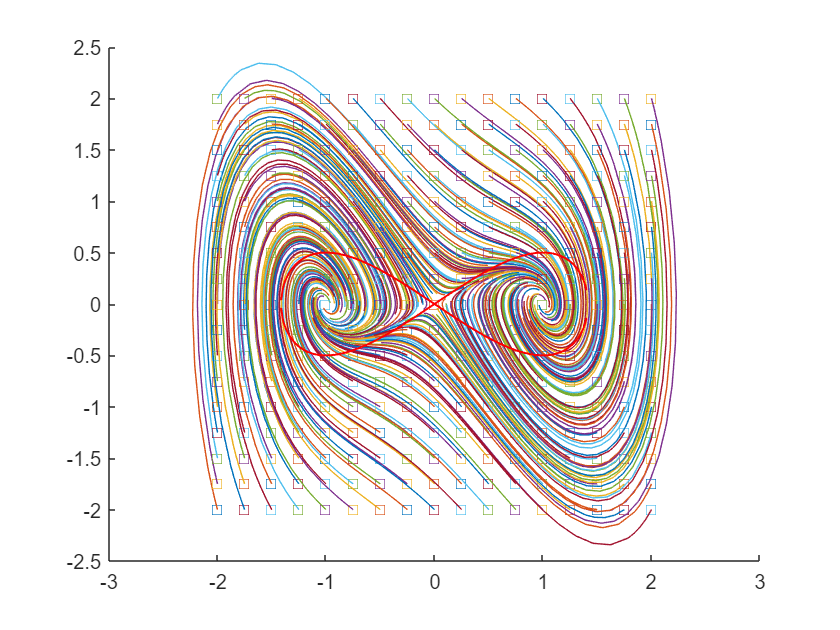

plot(x,yp,'r',"LineWidth",1)
plot(x,ym,'r',"LineWidth",1)

## Problema 2

Sistema

w = 8e-4;

A = [0 1 0 0
     3*w*w 0 0 2*w
     0 0 0 1
     0 -2*w 0 1];

B = [0 0; 1 0; 0 0; 0 1];

(2.1) Comprobamos si la órbita es estable

[vecA, eigA] = eig(A)

vecA =          0    1.0000    1.0000    0.0011
         0   -0.0014    0.0014    0.0011
    1.0000    0.0016    0.0016    0.7071
         0   -0.0000    0.0000    0.7071


eigA =          0         0         0         0
         0   -0.0014         0         0
         0         0    0.0014         0
         0         0         0    1.0000


Hay dos valores propios positivos, así que no es estable. (Ver ecuación 5.18)

(2.2) Vamos a ver si el sistema es estabilizable y observable (el estado 2 no se puede medir)

C = [1 0 0 0
     0 0 1 0
     0 0 0 1];

[vecAt, eigAt] = eig(A');
B'*vecAt

ans =    -1.0000    1.0000   -0.0016    0.0000
    0.0016   -0.0016    1.0000   -0.7071


Es controlable, ningún autovector de A' pertenece al kernel de B' (Ver Teorema 6.2.4)

C*vecA

ans =          0    1.0000    1.0000    0.0011
    1.0000    0.0016    0.0016    0.7071
         0   -0.0000    0.0000    0.7071


Es observable, ningún autovector de A pertenece al kernel de C (Ver Teorema 6.4.3)

La respuesta es por tanto que sí podemos salvar a la Valkyrie

(2.3) Vamos a diseñar un estimador y un controlador LQR

Diseñamos un estimador rápido

L = (place(A',C',[-4, -6, -8, -10]))' % Sistema dual Teorema 6.3.3

L =    15.9897         0   -1.1088
   60.0275         0   -8.5314
         0    4.0000    1.0000
   -0.1115         0    9.0103


Diseñamos la Q y R para LQR

rho = 1;
% La norma de x no puede ser mayor que 10
% Máximo valor admisible para cualquier componente: si 
% todas son iguales a 100/4 (al cuadrado), entonces la norma de x es 10.
Qbar = 4/100*eye(4);
Rbar = 1/(100*100)*eye(2);

G = eye(4); % Atencion, el LQR lo quiero para los 4 estados (eq 6.61)
H = zeros(4,2); % Las mismas dimensiones que B porque G tiene las mismas dimensiones que A
Q = G'*Qbar*G;
R = H'*Qbar*H + rho*Rbar;
N = G'*Qbar*H;

K = lqr(A,B,Q,R,N)

K =    20.0000   20.9762   -0.0015   -0.0000
    0.0015   -0.0000   20.0000   22.0000


(2.4) 

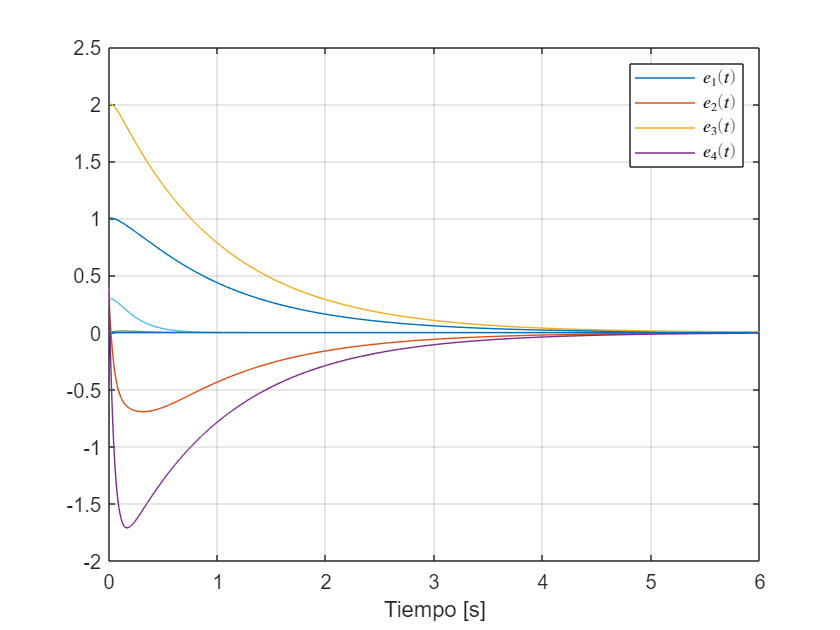

D = zeros(3,2); % La salida es un vector de 3 componentes (las mediciones), y tenemos 2 entradas.
[t,x] = ode45(@(t,X) estimador_controlador_Valkyrie(t,X, A, B, C, D, K, L),[0, 6], [1, 0.3, 2 , 0.4, 1, 0, 2, 0.4]);

figure(2)
plot(t, x(:,1))
hold on
grid on
plot(t, x(:,2))
plot(t, x(:,3))
plot(t, x(:,4))
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$','$x_4(t)$','Interpreter','latex')
xlabel('Tiempo [s]')

figure(2)
plot(t, x(:,1)-x(:,5))
hold on
grid on
plot(t, x(:,2)-x(:,6))
plot(t, x(:,3)-x(:,7))
plot(t, x(:,4)-x(:,8))
legend('$e_1(t)$','$e_2(t)$','$e_3(t)$','$e_4(t)$','Interpreter','latex')
xlabel('Tiempo [s]')

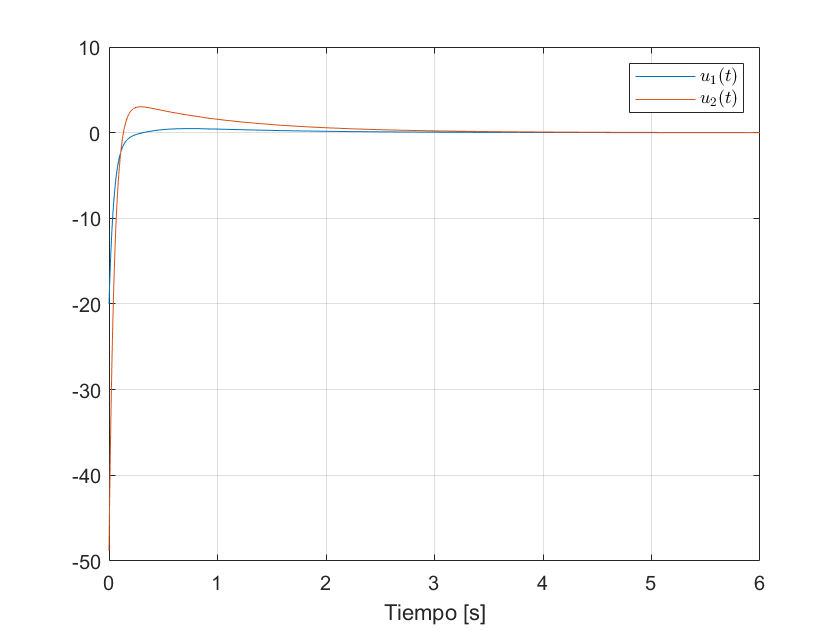


figure(3)
plot(t, -K*x(:,5:8)') % Pintamos la senal de control aplicada, u = -K*xhat
legend('$u(t)$','Interpreter','latex')
xlabel('Tiempo [s]')
legend('$u_1(t)$','$u_2(t)$','Interpreter','latex')
grid on

(2.5) Vamos a ver la controlabilidad en caso de que perdiéramos uno de los dos actuadores

Bsolorad = [0 0; 0 0; 0 0; 0 1];
Bsolotan = [0 0; 1 0; 0 0; 0 0];

Bsolorad'*vecAt % No pasa nada si perdemos el tangencial

ans =          0         0         0         0
    0.0016   -0.0016    1.0000   -0.7071


Bsolotan'*vecAt % Aquí perdemos controlabilidad, hay que proteger el radial!

ans =    -1.0000    1.0000   -0.0016    0.0000
         0         0         0         0


(2.6) Vamos a ver la observabilidad en caso de que perdamos sensores

C13 = [1 0 0 0
       0 0 1 0];
C14 = [1 0 0 0
       0 0 0 1];
C34 = [0 0 1 0
       0 0 0 1];
C1 = [1 0 0 0];
C3 = [0 0 1 0];
C4 = [0 0 0 1];

C13*vecA % No perdemos obs

ans =          0    1.0000    1.0000    0.0011
    1.0000    0.0016    0.0016    0.7071


C14*vecA % Perdemos obs

ans =          0    1.0000    1.0000    0.0011
         0   -0.0000    0.0000    0.7071


C34*vecA % No perdemos obs

ans =     1.0000    0.0016    0.0016    0.7071
         0   -0.0000    0.0000    0.7071


C1*vecA % Perdemos obs

ans =          0    1.0000    1.0000    0.0011


C3*vecA % No perdemos obs! PODEMOS OPERAR CON SOLO 1 sensor!

ans =     1.0000    0.0016    0.0016    0.7071


C4*vecA % Perdemos obs

ans =          0   -0.0000    0.0000    0.7071



% Siempre y cuando no perdamos el sensor que mide x3,
% estamos bien

## Problema 3

(3.1) Vemos los autovalores y autovectores de A

A = [-1 1 0
      1 -2 1
      0  1 -1];

[vecA, eigA] = eig(A) % El autovalor 0 tiene eigvec con todos los elementos iguales

vecA =    -0.4082   -0.7071    0.5774
    0.8165    0.0000    0.5774
   -0.4082    0.7071    0.5774


eigA =    -3.0000         0         0
         0   -1.0000         0
         0         0   -0.0000


% por lo que las temperaturas convergen a una en común, Eq 5.18

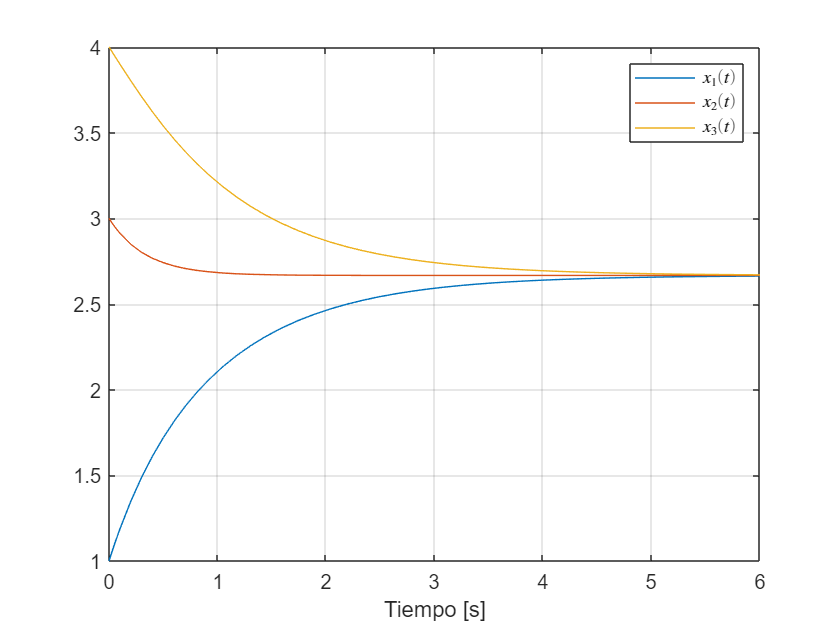


% Comprobamos numéricamente
[t,x] = ode45(@(t,X) habitacion_temp(t,X, A),[0, 6], [1, 3, 4]);
figure(4)
plot(t, x(:,1))
hold on
grid on
plot(t, x(:,2))
plot(t, x(:,3))
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$','Interpreter','latex')
xlabel('Tiempo [s]')

(3.2) Analizamos el sistema z(t)

Az = [-2 1; 1 -2];
[vecAz, eigAz] = eig(Az) % Todos los autovalores son negativos. 

vecAz =     0.7071    0.7071
   -0.7071    0.7071


eigAz =     -3     0
     0    -1


% Todas las diferencias de temperatura convergen a cero

(3.3a) Vamos a ver las opciones posibles para actuar. Como antes, solo con probar B1 y B2 valdría.

B1 = [1 0 0]';
B2 = [0 1 0]';
[vecAt, eigAt] = eig(A');

B1'*vecAt % Es controlable

ans =    -0.4082   -0.7071    0.5774


B2'*vecAt % No es controlable

ans =     0.8165    0.0000    0.5774



% Con poner la bomba en 1 o 3 el sistema ya es controlable

(3.3b) Solo se pedía la entrada en función de x(t0) y x(t1).

u(t) = B'*expm(A'*(t1-t))*eta;  donde eta es una solución a

x(t1) - x(t0) = Wr * eta, donde Wr es el Grammian de alcanzabilidad. (Mirar ATENCION 6.2.1)

Lo siguiente no se pedía en el exámen, pero es la comprobación numérica sobre que la u(t) propuesta es cierta.

A = [-1 1 0
     1 -2 1
     0  1 -1];
B = [1;0;0]; % Una bomba solo en la hab de la izquierda
t1 = 10; % Tiempo final arbitrario
dt = 0.001; % Paso de tiempo para la integración por Euler
Wr = gramfun(t1,A,B,dt); % Hacemos la integración numérica
x1 = [270;265;280]; % Estado final arbitrario
a = 273;
x = [a;a;a]; % Estado inicial de equilibrio arbitrario
eta = inv(Wr)*(x1-x); % Tenemos la suerte de que Wr es positiva definida en este caso

% Simulacion numerica, integro por Euler
log_t = 0:dt:t1;
log_u = zeros(length(log_t),size(B,2));
log_x = zeros(length(log_t),3);

for i  = 1:length(log_t)
    t = log_t(i);
    u = B'*expm(A'*(t1-t))*eta;
    dxdt = A*x +B*u;
    x = x + dxdt*dt;
    log_u(i,:) = u;
    log_x(i,:) = x;
end

% Comprobamos que llegamos a x1 en el tiempo t1.
x % Con error numérico por la integración cutre para el cálculo de Wr

x =   270.0125
  264.9943
  279.9932


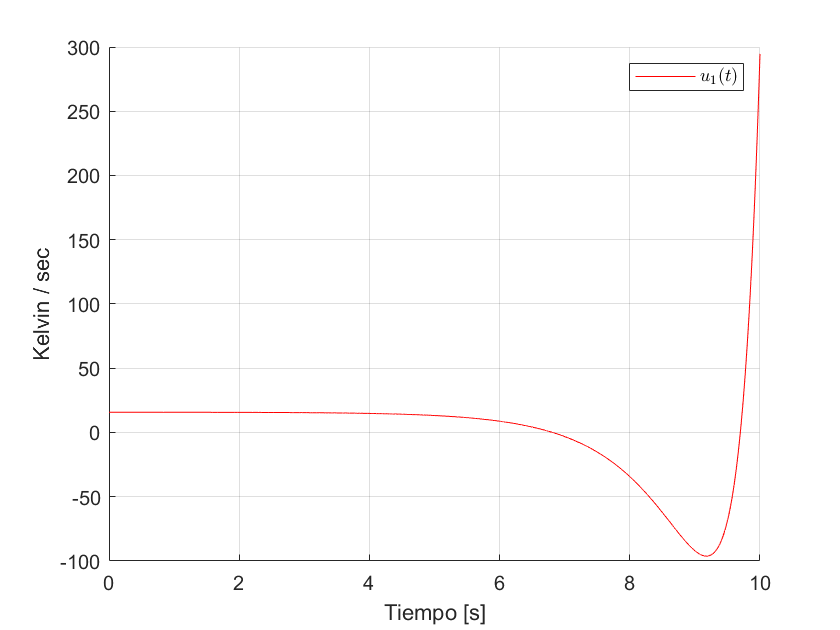


figure(10)
hold on
% Pintamos la señal de entrada a la habitación de la izquierda
plot(log_t,log_u(:,1),'r')
grid on
legend('$u_1(t)$','Interpreter','latex')
xlabel('Tiempo [s]')
ylabel('Kelvin / sec')

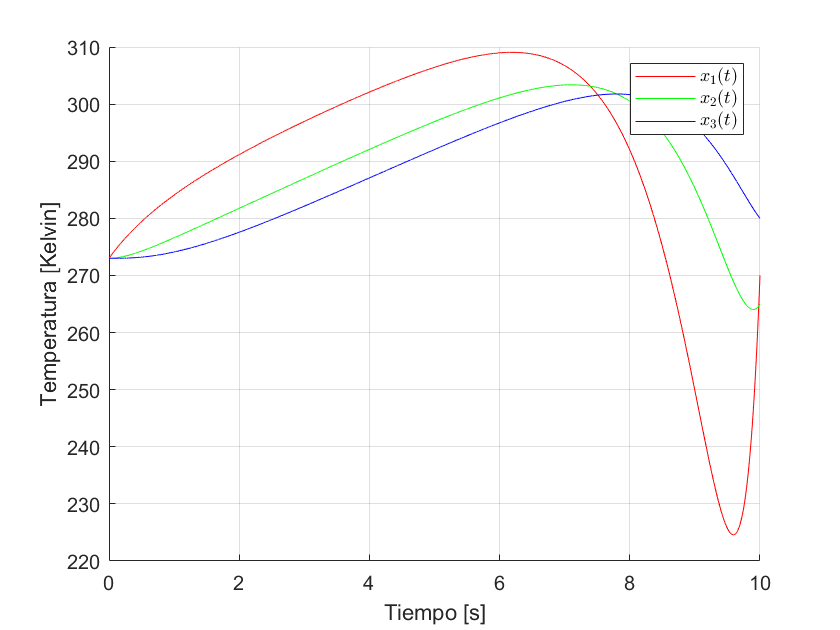


figure(11)
hold on
plot(log_t,log_x(:,1),'r')
plot(log_t,log_x(:,2),'g')
plot(log_t,log_x(:,3),'b')
grid on
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$','Interpreter','latex')
xlabel('Tiempo [s]')
ylabel('Temperatura [Kelvin]')

function dx = duffinf(t,x)
dx(1,1) = x(2,1);
dx(2,1) = -x(2,1)-x(1,1)^3+x(1,1);
end

function dXdt = estimador_controlador_Valkyrie(t, X, A, B, C, D, K, L)

Ahat = A; % Eq. 6.56
Bhat = B;
Chat = C;
Dhat = D;

x = X(1:4);      % Estos son los cuatro estados
xhat = X(5:8);   % Estas son las cuatro estimaciones de los estados

u = -K*xhat; % Esta es la senal de control a los dos motores eq 6.58
y = C*x; % Esto es lo que podemos medir con los sensores
yhat = Chat*xhat + Dhat*u; % Esta es la salida estimada 6.56

dot_x = A*x + B*u; % Simulamos el sistema
dot_xhat = Ahat*xhat + Bhat*u - L*(yhat - y); % Calculamos las derivadas del estimador

dXdt = [dot_x ; dot_xhat]; % Las derivadas temporales de los estados y sus estimaciones

end

function dXdt = habitacion_temp(t, X, A)

dXdt = A*X; % Simulamos el sistema

end

function wr = gramfun(t1,A,B,dt)
% Calcula numéricamente el Gramian de alcanzabilidad Eq 6.17
wr = zeros(size(A));

for t=0:dt:t1
    wr = wr + expm(A*(t1-t))*B*B'*[expm(A*(t1-t))]'*dt;
end

end